close all; clear; clc;

## **Basic Description**

    The Input image is a 255*270 pixels gray-scaled image. As this image shown, the texture between cheetah, which is our object and foreground, and grass is quite different. The background(grass) has more uniform intensities than the foreground, which can make a seperation in frequenct domain. Our purposed method is statistical learning with bayesian decision theory using features in frequency domauin. Firstly, to take each component in the rule, its necessary to understand how the data distributed by prior probability.

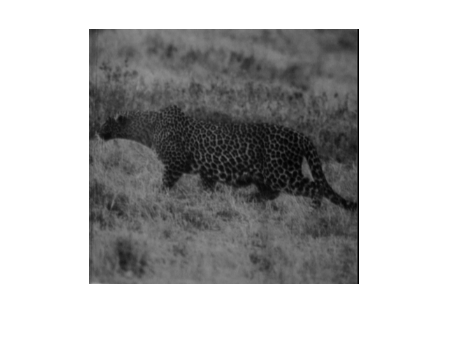

%% Data import

img = imread('cheetah.bmp');
imshow(img);

zz_order = dlmread('Zig-Zag Pattern.txt');
load('TrainingSamplesDCT_8.mat');
N = 8;

## Prior Probability

    The prior probabilities can be simply acquired by calculating the ratio of two classes in training samples. The prior probability of foreground is 0.1919, and 0.8081 for background. This question simply takes this "cheetah segmentation" as binary classification, which composed of two classes. And we can observe that the ratio of background is much higher than foreground.

%% Problem 1: Priors
% Priors of background and foreground are directly acquired by calculate
% the ratio of traing samples in each class

c_size = size(TrainsampleDCT_FG,1);
g_size = size(TrainsampleDCT_BG,1);

P_c = c_size / (c_size + g_size);
P_g = g_size / (c_size + g_size);

disp('Prior probability of cheetah:')

Prior probability of cheetah:


disp(P_c)

    0.1919



disp('Prior probability of grass:')

Prior probability of grass:


disp(P_g)

    0.8081




% Feature vector: location of the coefficient of 2nd largest magnitude,
BG_X = feature_vector_DCT(TrainsampleDCT_BG);
FG_X = feature_vector_DCT(TrainsampleDCT_FG);

## Conditional Probability given Class

    By using discrete cosine transform(DCT), which can be taken as "real" Fourier Transform, we can map an image block into an array of frequency coefficient which captures image information in frequncy domian. The location of 2nd highest enery value in this coefficient array is taken as feature and random variable X, which provides spatial information with higher intensity gradient. The Trainsample_BG/FG provides the conditional probability of X given these two classes, and we can show their distribution by histogram as below shown.

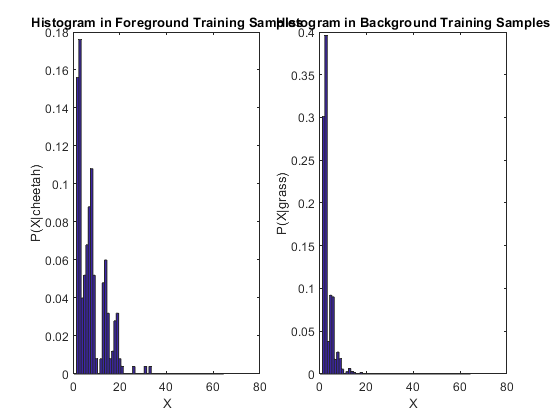

%% Problem 2: Conditional Probability Given Classes
% Conditional probabilities of X given cheetah/grass can be acquired by
% the histogram of DCT images, which contains locations of 2nd highest
% energy value within each 8*8 blocks in training samples.
% The conditional probabilities are ratio of each X. 

bin_ranges=0.5:1:63.5; % 64 bins for plot
P_X_given_c_vec = DCT_histogram(FG_X,8); % Scale to [0,1]
P_X_given_g_vec = DCT_histogram(BG_X,8); % Scale to [0,1]

figure;
subplot(1,2,1)
bar(bin_ranges,P_X_given_c_vec,'histc')
title('Histogram in Foreground Training Samples')
xlabel('X')
ylabel('P(X|cheetah)')

subplot(1,2,2)
bar(bin_ranges,P_X_given_g_vec,'histc')
title('Histogram in Background Training Samples')
xlabel('X')
ylabel('P(X|grass)')

## Binary Mask Generation

    Next, we dig into central idea of this question: what is the difference between foreground and background? The probability of two classes given random variable X is the answer: we can use this probability to determine which classe this pixel belongs to. 

    In detail, we used DCT to calculate a 8*8 frequency coefficient array within a subimage with the same size. This array served as features in the origin of this subimage, which is the left-top corner. The DCT window is slided through every subimage in the the whole picture with one-pixel step. Then, this array is flatten into a 64-dim feature vector, ordered by zig-zag order recorded in Zig-Zag Pattern.txt. As a result, we can acquire feature vectors of these subimages to represent their corresponding pixels. 

    The defect of my implementation is the sliding window, which can only process in range from (0,0) to (height - subimage height, width - subimage width). So, we will see a 8-pixels thick border outside the prediction, but not influence the most part of my prediction.

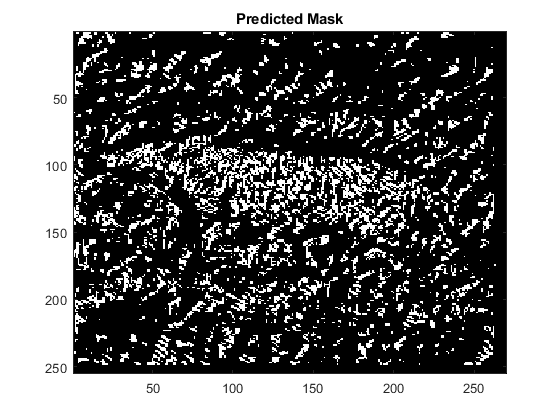

%% Problem 3: Mask Generation
binary = 0;
sub_img_X_map = zeros(size(img));

% Take left top pixel in a block as origin
% The last N-1 pixels are taken as padding
for r = 1:size(img,1)-N+1
    for c = 1:size(img,2)-N+1
        sub_img = img(r:r+N-1, c:c+N-1); % 8*8 block image
        sub_img_DCT = dct2(sub_img); 
        sub_img_X = X_by_DCT(sub_img_DCT, zz_order); % The ouput is a scalar, which indicates X
        sub_img_X_map(r,c) = sub_img_X; % A map recorded each X in all pixels
    end
end

A = zeros(size(img));
for r = 1:size(img,1)-N+1                           
    for c=1:size(img,2)-N+1
        if P_X_given_c_vec(sub_img_X_map(r,c)) * P_c > P_X_given_g_vec(sub_img_X_map(r,c)) * P_g
            A(r,c)=1;
        else
            A(r,c)=0;
        end
    end
end
A = uint8(A) * 255;

figure
imagesc(A)
title('Predicted Mask')
colormap(gray(255))

    This is a binary mask I generated. White pixels represent the predicted foreground class and black for background. As the result shown, we can see an approximated contour of cheetah in the middle of picture and dense bulks of white pixels within this area. Also, due to the circle patterns in cheetah's body, there are lots of alternative white-black regions within the contour. In ouside of middle, there are some small bulks of white pixels, and I think this is because of some high intensities in different area of grass, which bring informative changes in frequency domain, such as thin branches in shrub. 

masked = A ./ 255 .* img 

masked = 255×270 uint8 matrix
     0     0     0     0    47     0     0    60    57    61    68    69     0    71    78    83     0     0     0     0    98     0     0     0     0     0     0   106   113     0     0     0     0     0   124   125     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0    55    48     0     0    55    66    62    65    72     0     0    76    85     0     0     0     0     0   103   100     0     0     0     0   100     0     0     0     0     0     0     0     0   126     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0    61    71    67    71     0     0     0    83    91     0     0     0     0     0     0   107   104     0    97     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   132   129     0
     0     0     0     0     0     0    72    81    73    77    84 

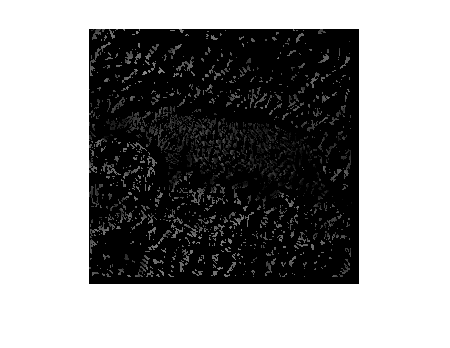

figure
imshow(masked)

## The Error Rate

%% Problem 4: Error Rate
ground_t = imread('cheetah_mask.bmp');
err = 0;
for r = 1:size(A,1)
    for c = 1:size(A,2)
        if ground_t(r,c) ~= A(r,c)
            err = err + 1;
        end
    end
end

disp('Error rate(%):');

Error rate(%):


disp(err / size(A,1) / size(A,2) * 100);

   23.8126



    The overall error rate is 23.8%. For improvement, I think more features are necessary because the random variable X, which represents spatial information by frequency domain energy, would be sensitive to intensity changes in any object, including grass. Probably the contour should be better seperated by algorithms, then apply regional image processing, like thresholding, to increase more attention on the area within contour and decrease in outside regions. Or blur the image to decrease all intensity gradients.